# Estimating recession parameters with the point cloud method

## Introduction

This example demonstrates how to detect recession events, and then estimate recession parameters $a$ and $b$ using the "point cloud" method. We use daily streamflow data measured in the Kuparuk River Basin on the North Slope of Alaska. Daily streamflow data are provided by the United States Geological Survey, recorded at streamflow gage 1596000. The data are included in the `data/` folder as a sample dataset with this toolbox, or can be downloaded from [https://waterdata.usgs.gov/monitoring-location/15896000.](https://waterdata.usgs.gov/monitoring-location/15896000.)

## Preparing data for recession analysis

The minimum required information to fit recession parameters is a timeseries of daily streamflow. The drainage area of the upstream river basin, and values for drainage density, stream channel length, basin slope, and aquifer thickness are used by other functions in the toolbox, and are explored in other examples.

The `basinname` function returns a pre-formatted string from a database of streamflow gages included with the toolbox in `data/stationlist.mat`. The station names in the database are the official USGS station names. This is not required, but is useful for creating plot lables, filenames, and passing to other toolbox functions. Use tab-completion to set the argument to the `basinname` function.

Start with a clean workspace, then set the sitename. 

clearvars
close all
clc

Use tab-completion to set the argument to the `basinname` function.

sitename = baseflow.basinname('KUPARUK R NR DEADHORSE AK'); %#ok<*NASGU> 

Load streamflow data for the test basin into the workspace. In the sample dataset, the variable `T` is *time*, `Q` is *discharge*, and `R` is *rainfall*.

[T, Q, R] = baseflow.loadExampleData();

## Plot the input data

Plot one year of the streamflow and precipitation data using the `baseflow.hyetograph` function.

t1 = datenum(datetime(1992, 6, 1)); %#ok<*DATNM>
t2 = datenum(datetime(1992, 12, 1));
H = baseflow.hyetograph(T, Q, R, t1, t2, 'units', {'m3 d-1', 'mm d-1'});

Get the handle to the streamflow axis, then set the y-axis to log scale to see the shape of the recession curve in more detail.

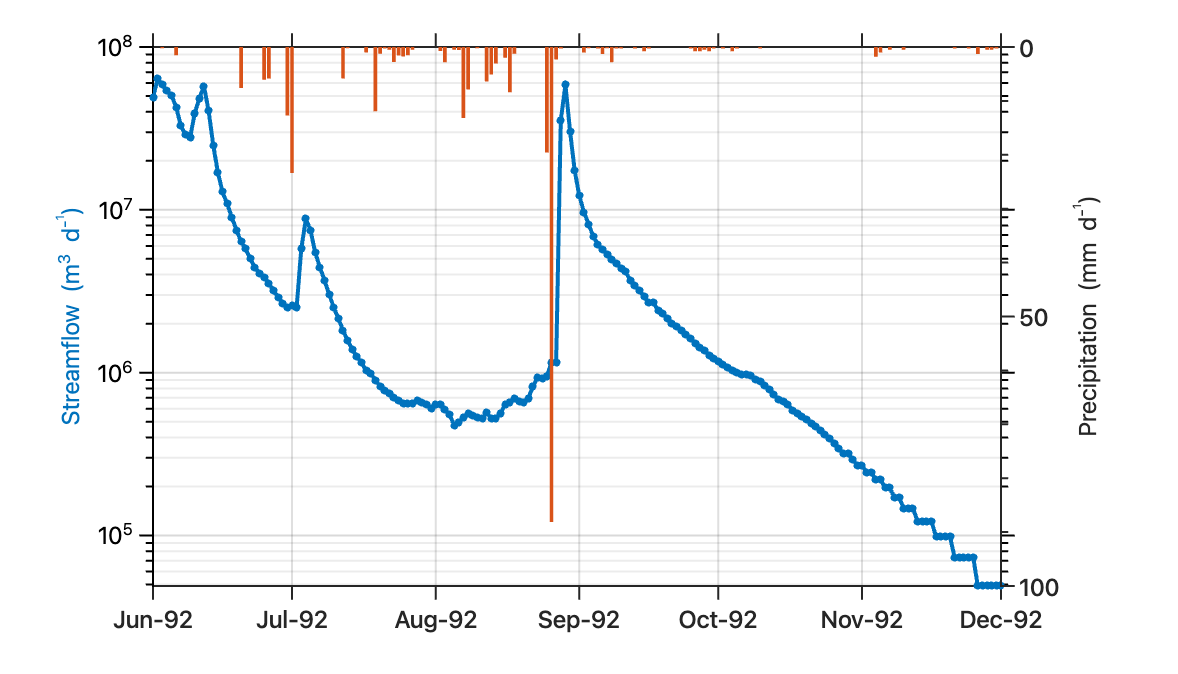

set(findobj(H, 'Tag', 'HyetographAxis'), 'YScale', 'log'); 

The toolbox includes a helper function `baseflow.getstring()` that returns formatted latex strings for plot labels. The `getstring` function assumes the data has the units assumed by functions throughout the toolbox, which serves as a useful reminder when preparing data for analysis. Replace the ylabel created by `baseflow.hyetograph` with the formatted string returned by `getstring`. 

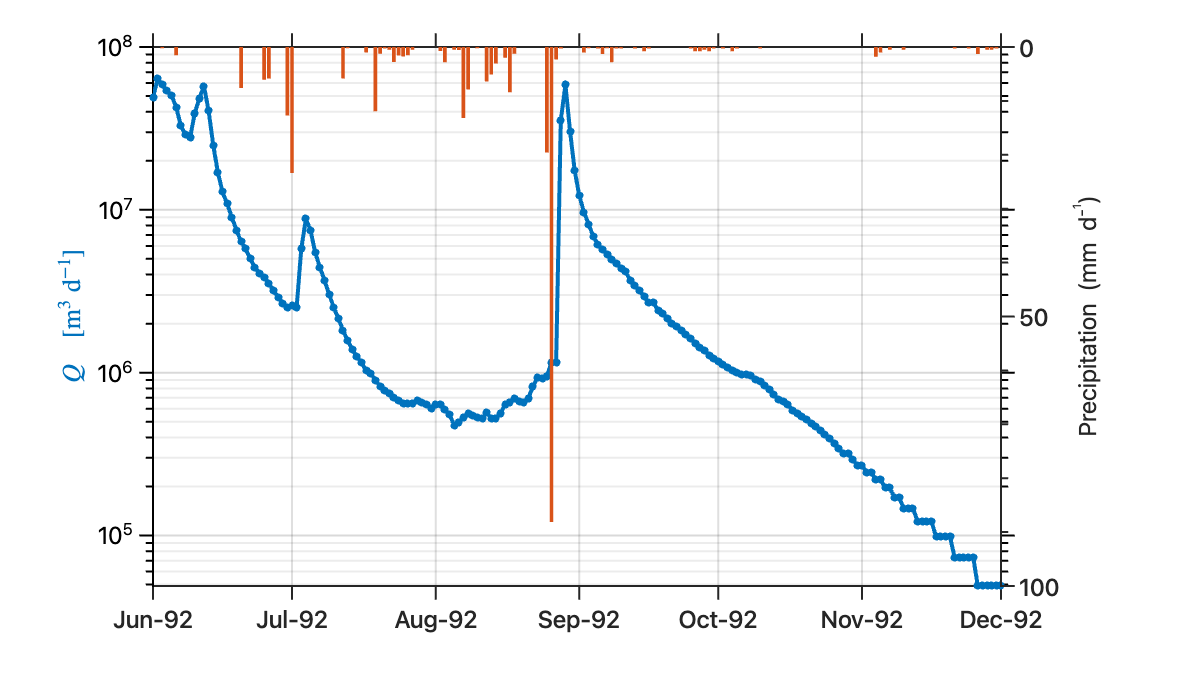

ylabel(baseflow.getstring('Q', 'units', true), 'Interpreter', 'latex');

## Detecting recession events from timeseries of daily streamflow

The toolbox supports three main tasks: recession event detection, recession event curve-fitting, and parameter estimation via distribution fitting. The `setopts` function provides an interface to set options that control the algorithms used to implement these tasks. The function accepts three possible inputs, each correspond to another function in the toolbox used for the three main tasks mentioned above: `getevents`, `fitevents`, and `globalfit`. The term "globalfit" differentiates two fitting procedures: one that fits individual recession events to estimate parameters specific to each  particular event (which is the purpose of `fitevents`), and another that fits a collection of events to derive a "global" parameter value applicable to the entire sample population (the purpose of `globalfit`)

Default values are set by `setopts` automatically. In this example, we use the default options for `getevents` and `fitevents`. We will not use `globalfit` in this example.

Set the algorithm options.

opts.getevents = baseflow.setopts('getevents');
opts.fitevents = baseflow.setopts('fitevents');

The following steps demonstrate a typical workflow in baseflow recession analysis. The steps consist of getting a list of recession events, fitting the recession events, and then estimating the recession parameters *a* and *b*. In this example, we use the point cloud method to fit these recession parameters.

### Step 1. Get events

EventData = baseflow.getevents(T, Q, R, opts.getevents);

### Step 2. Fit events

[EventFits, FitsTable] = baseflow.fitevents(EventData, opts.fitevents);

### Step 3. Fit recession parameters *a* and *b*

Pass the event discharge data $Q$ and recession rate $dQ/dt$ to baseflow.fitab with fitting method set to `nls` for "nonlinear least squares". Generate a point-cloud plot by setting `plotfit` to `true`. 

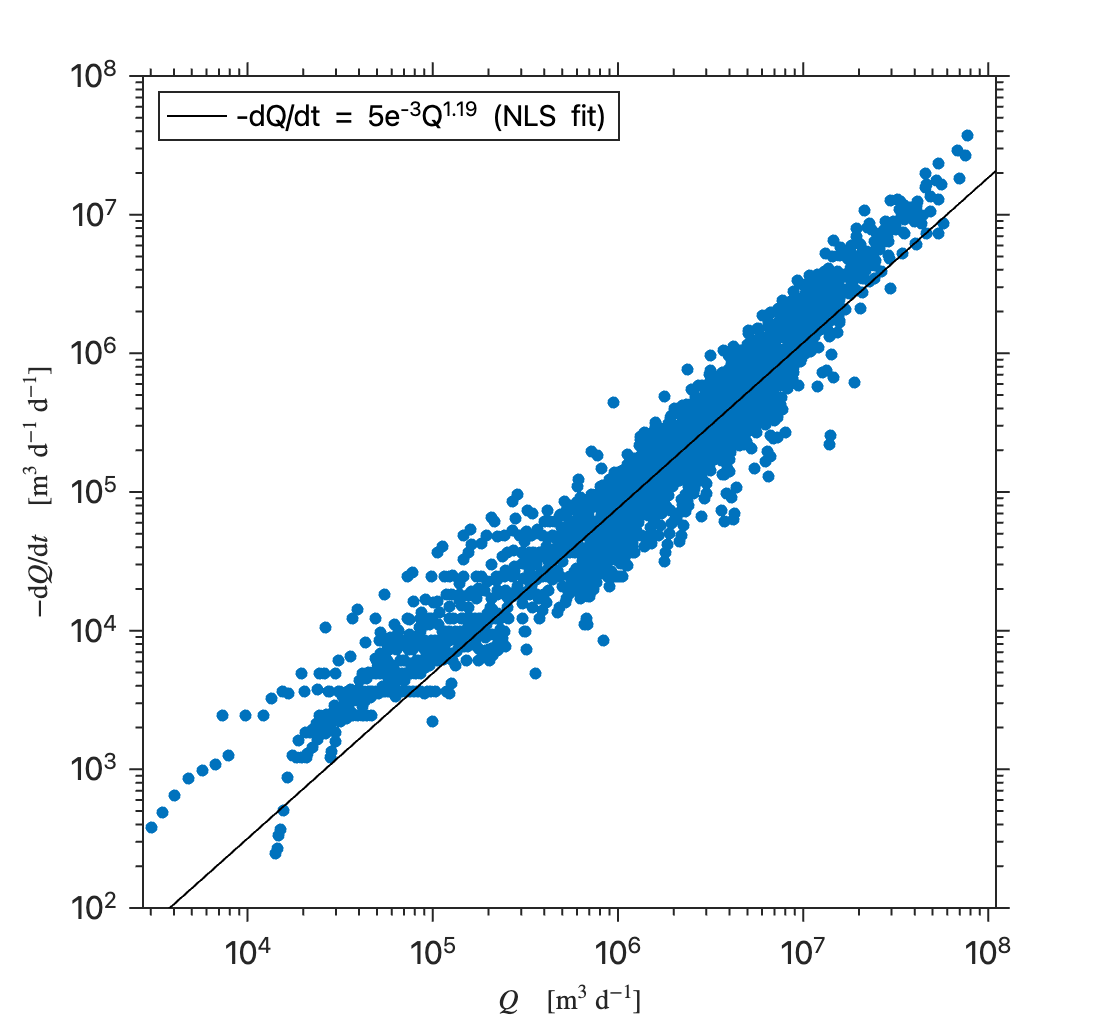

abFit = baseflow.fitab(EventFits.q, EventFits.dqdt, 'nls', 'plotfit', true);

## Check the fitted recession parameters

The recession parameters *a* and *b* in the recession equation $-dQ/dt = aQ^b$ are available in the `abFit` struct.

abFit.a

ans = 0.0054

abFit.b

ans = 1.1915

Print the fitted values to the screen using a latex-formatted character array. This is the same function used to format the legend in the point cloud plot shown above.

baseflow.aQbString([abFit.a abFit.b], 'printvalues', true)

ans = '-d$Q$/d$t$ = 5e$^{-3}Q^{1.19}$'

The fitted value *b=1.2 *indicates the reservoir is mildly non-linear.